load Q_degradation.csv
load R0_degradation.csv

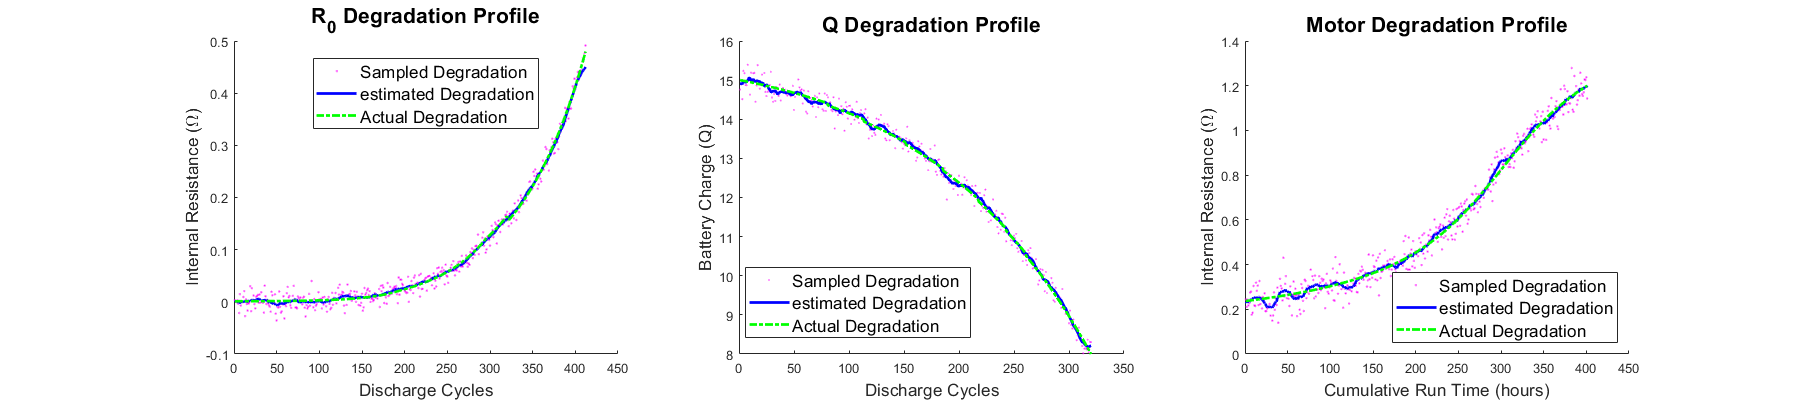

rdeg = interp1([R0_degradation(1) R0_degradation(end)], [.0011 0.48], R0_degradation);
rdegr = normrnd(rdeg, .013);
restr = movmean(rdegr, 22);

frdeg = figure("Name", "rdeg"); clf;
frdeg.Position = [0 0 1800 400];
subplot(1,3,1);
hold on;
plot(rdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(restr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(rdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);


qdeg = interp1([Q_degradation(1) Q_degradation(end)], [15 8], Q_degradation);
qdegr = normrnd(qdeg, .2);
qestr = movmean(qdegr, 10);
subplot(1,3,2);
% fqdeg = figure("Name", "qdeg"); clf;
% fqdeg.Position = [0 0 800 400];
hold on;
plot(qdegr, 'm.', 'markersize', 1, "DisplayName", "Sampled Degradation");
plot(qestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(qdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
x = -15:.05:05;
y = atan(x/5)/7;
mdeg = interp1([y(1) y(end)], [.2371 1.2], y);
mdegr = normrnd(mdeg, .05);
mestr = movmean(mdegr, 15);
% fmdeg = figure("Name", "mdeg"); clf;
% fmdeg.Position = [0 0 800 400];
subplot(1,3,3);
hold on;
plot(mdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(mestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(mdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);

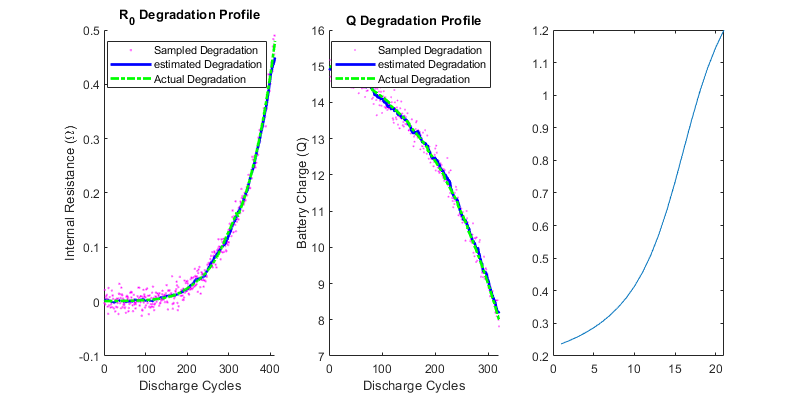

rdown = downsample(rdeg, 18);
qdown = downsample(qdeg, 15);
mdown = downsample(mdeg, 20)';
plot(rdown);
%save('params\rdown.mat', 'rdown');
plot(qdown);
%save('params\qdown.mat', 'qdown');
plot(mdown);

%save('params\mdown.mat', 'mdown');

motor

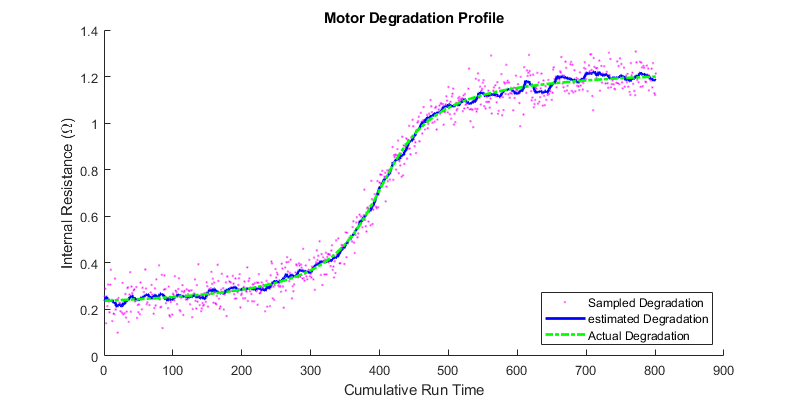

hrs = 17*400/60;

cycle = length(qdown);
ret = interp1([0 33], [0 196], 0:2.9:27);
ret

idx=1:1:12;

ret =          0   17.2242   34.4485   51.6727   68.8970   86.1212  103.3455  120.5697  137.7939  155.0182


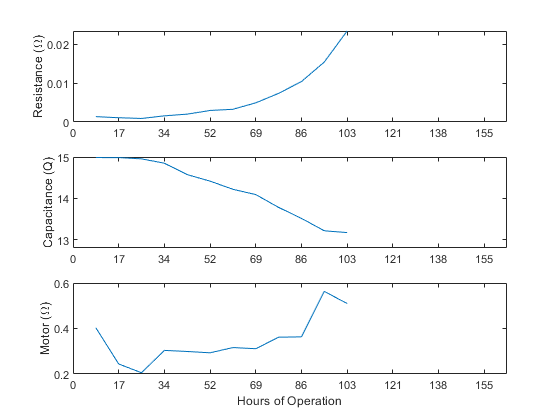


r0t = true_params(:,1);
qt = true_params(:,2);
mt = true_params(:,3);
f = figure(); clf;
subplot(3,1,1);
plot(idx, r0t(idx));
ylabel("Resistance (\Omega)");

xlim([0 19]);

xticklabels({sprintf("%d",round(ret(1))), sprintf("%d",round(ret(2))), sprintf("%d",round(ret(3))), sprintf("%d",round(ret(4))), ...
    sprintf("%d",round(ret(5))), sprintf("%d",round(ret(6))), sprintf("%d",round(ret(7))), sprintf("%d",round(ret(8))), ...
    sprintf("%d",round(ret(9))), sprintf("%d",round(ret(10)))});
subplot(3,1,2);
plot(idx, qt(idx));
ylabel("Capacitance (Q)");
xlim([0 19]);
ylim([12.8 15]);
title("");
xticklabels({sprintf("%d",round(ret(1))), sprintf("%d",round(ret(2))), sprintf("%d",round(ret(3))), sprintf("%d",round(ret(4))), ...
    sprintf("%d",round(ret(5))), sprintf("%d",round(ret(6))), sprintf("%d",round(ret(7))), sprintf("%d",round(ret(8))), ...
    sprintf("%d",round(ret(9))), sprintf("%d",round(ret(10)))});

subplot(3,1,3);
plot(idx, mt(idx));
ylabel("Motor (\Omega)");
xlim([0 19]);
title("");
xlabel("Hours of Operation");
xticklabels({sprintf("%d",round(ret(1))), sprintf("%d",round(ret(2))), sprintf("%d",round(ret(3))), sprintf("%d",round(ret(4))), ...
    sprintf("%d",round(ret(5))), sprintf("%d",round(ret(6))), sprintf("%d",round(ret(7))), sprintf("%d",round(ret(8))), ...
    sprintf("%d",round(ret(9))), sprintf("%d",round(ret(10)))});



x = 1:1:length(qdown);
x

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22


f = fit([1:1:length(qdown)]', qdown, 'poly4')

f =      Linear model Poly4:
     f(x) = p1*x^4 + p2*x^3 + p3*x^2 + p4*x + p5
     Coefficients (with 95% confidence bounds):
       p1 =  -1.322e-05  (-2.33e-05, -3.132e-06)
       p2 =   8.488e-06  (-0.0004586, 0.0004756)
       p3 =   -0.009951  (-0.01718, -0.002726)
       p4 =    -0.09096  (-0.1331, -0.04881)
       p5 =        15.1  (15.03, 15.18)

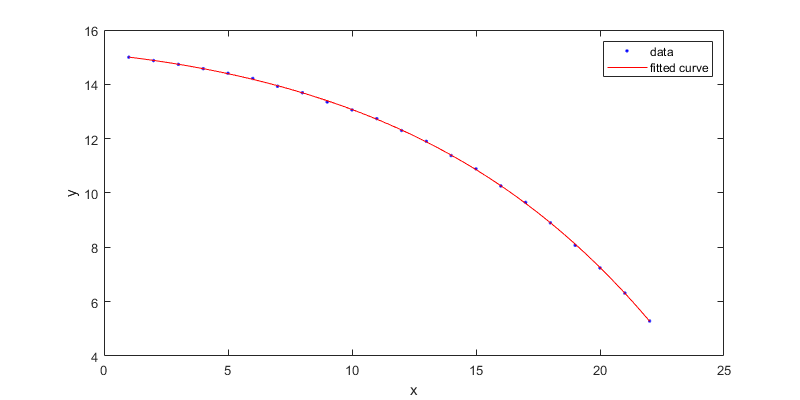

plot(f, x, qdown)

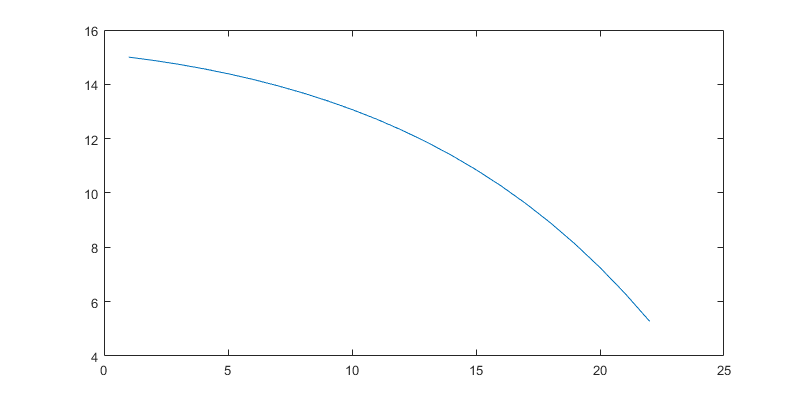

p = polyfit(x, qdown, 4);
yr = polyval(p, x);
plot(x, yr)

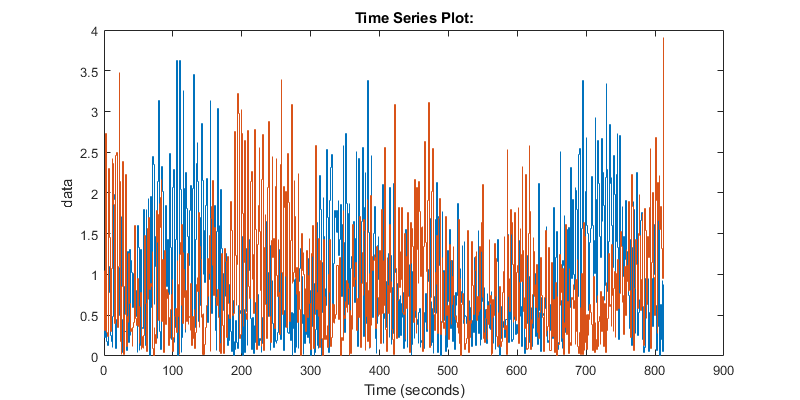

plot(pos_err)

mean(pos_err)

ans =     0.9290    0.9042


d = calculatedistance(path)

d = 1.3940e+03

t = calculatetime(d, 1.3)/60;
t(2)

ans = 17.8724

s = d/t(2)

s = 78

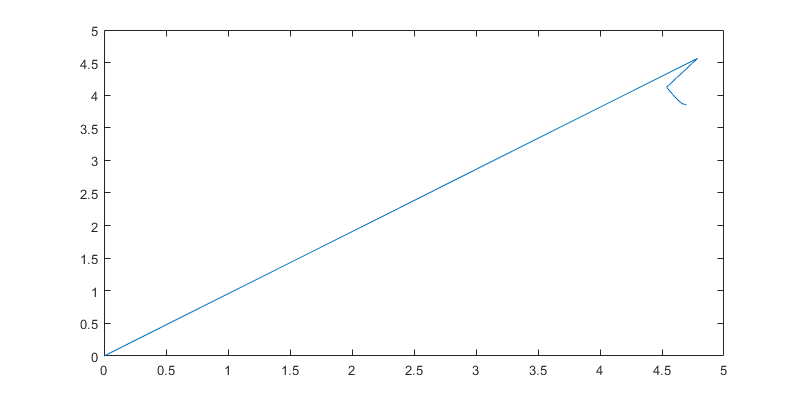

plot(pos_errs_twin(:,1), pos_errs_twin(:,2))

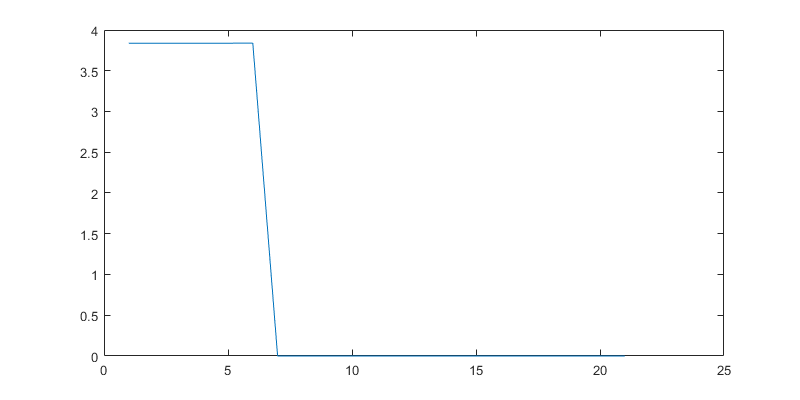

plot(pos_errs_twin(:,3));

%params = zeros(n_missions,3);
horizon = 5;
n_missions = 21;
j = 1;
polys = zeros(n_missions,3,2);
q_deg = zeros(n_missions, 1);
r_deg = zeros(n_missions, 1);
m_deg = zeros(n_missions, 1);
for i=1:n_missions
    %params(i,:) = [rdown(i), qdown(i), mdown(i)];
    sprintf("params: %f\t%f\t%f", rdown(i), qdown(i), mdown(i))
    q_deg(i) = normrnd(qdown(i), .075);
    r_deg(i) = normrnd(rdown(i), .00025);
    m_deg(i) = normrnd(mdown(i), .05);
    if i > horizon
        
        x = ((i-(horizon-1)):1:i)';
        r_poly = polyfit(x, smoothdata(r_deg((i-(horizon-1)):i)', 'rlowess', 5), 1);
        q_poly = polyfit(x, smoothdata(q_deg((i-(horizon-1)):i)', 'rlowess', 5), 1);
        m_poly = polyfit(x, smoothdata(m_deg((i-(horizon-1)):i)', 'rlowess', 5), 1);
        polys(i,1,:) = r_poly;
        polys(i,2,:) = q_poly;
        polys(i,3,:) = m_poly;
        
        twin_R0i = polyval(r_poly, i+2);
        twin_Q = polyval(q_poly, i+2);
        twin_RM = polyval(m_poly, i+2);
        %disp(params);
    else
        
        twin_R0i = .1;
        twin_Q = .2;
        twin_RMi = .3;
    end
end

ans = "params: 0.001100	15.000000	0.237100"

ans = "params: 0.001194	14.911929	0.247169"

ans = "params: 0.001341	14.814500	0.258599"

ans = "params: 0.001571	14.705512	0.271670"

ans = "params: 0.001932	14.584965	0.286738"

ans = "params: 0.002499	14.451207	0.304260"

ans = "params: 0.003387	14.250295	0.324825"

ans = "params: 0.004780	14.085162	0.349200"

ans = "params: 0.006966	13.846819	0.378379"

ans = "params: 0.010393	13.642604	0.413635"

ans = "params: 0.015768	13.416372	0.456544"

ans = "params: 0.023623	13.109774	0.508918"

ans = "params: 0.033131	12.830699	0.572492"

ans = "params: 0.044945	12.465755	0.648179"

ans = "params: 0.060342	12.121176	0.734845"

ans = "params: 0.081126	11.683573	0.828272"

ans = "params: 0.109181	11.258630	0.921699"

ans = "params: 0.139924	10.731305	1.008365"

ans = "params: 0.162416	10.152237	1.084052"

ans = "params: 0.203163	9.569867	1.147626"

ans = "params: 0.254194	8.923095	1.200000"

disp(twin_R0i)

    0.3156



disp(polyval(r_poly, i))

    0.2452



f10 = figure(10); clf;
hold on;
for i = 5:20
    x = [i+2];
    poly = [polys(i,3,1) polys(i,3,2)];
    y = polyval(poly, x)
    plot(x, y, 'ro', 'markersize', 8);
    xlim([0 25]);
    %ylim([0 .4]);
    pause(.1)
end

y = 0

y = 0.3191

y = 0.2875

y = 0.5153

y = 0.4426

y = 0.4676

y = 0.5142

y = 0.5030

y = 0.6824

y = 0.8036

y = 0.8581

y = 0.9367

y = 1.1493

y = 1.1687

y = 1.2699

y = 1.2480

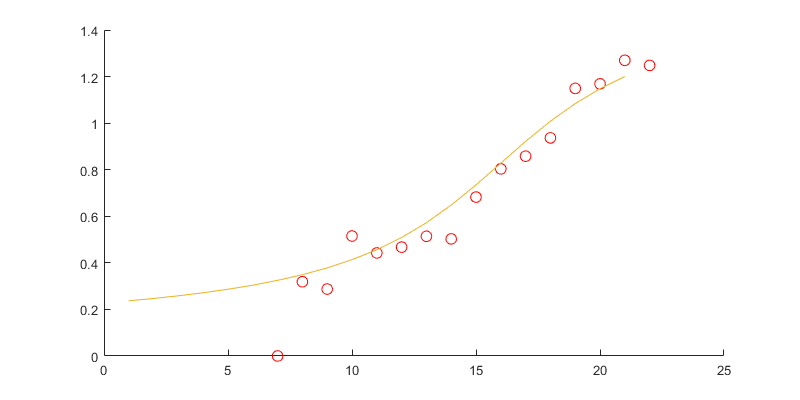

plot(mdown);
hold off;

r_poly

r_poly =     0.0007    0.1370


[polys(5,1,1) polys(5,1,2)]

ans = 	1.0e+-3 *

    0.2041    0.8151


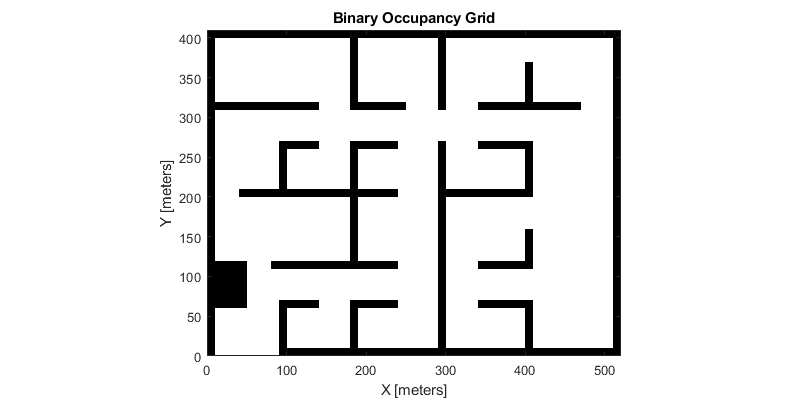

x = pos.Data(:,1);

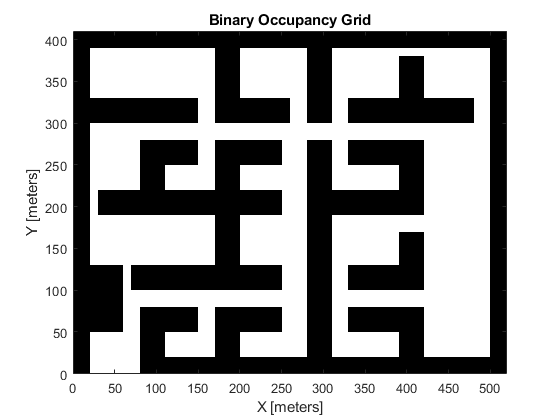

y = pos.Data(:,2);
x = downsample(x, 50);

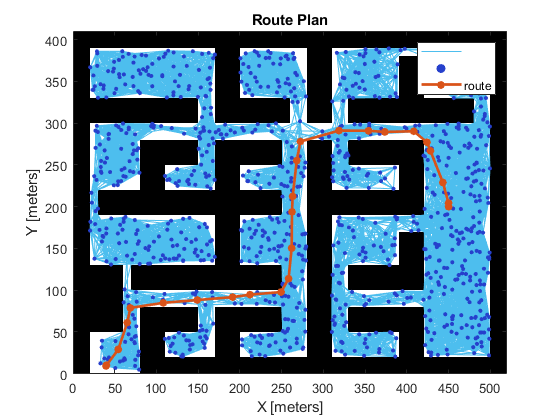

y = downsample(y, 50);
% map processing
load maps/complexmap.mat ;
Resolution=0.1; % meters
f3 = figure(3); clf;

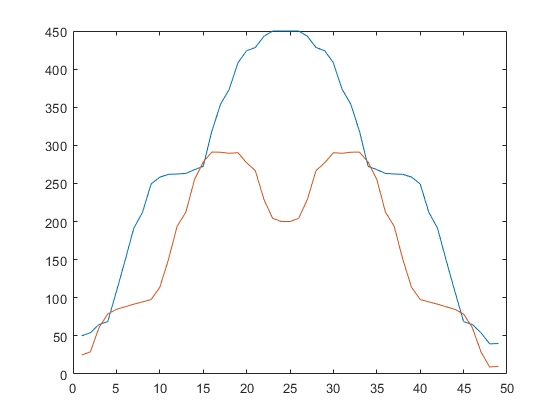

map = binaryOccupancyMap(complexMap,Resolution);

hold on;

Unrecognized function or variable 'pathLength'.

show(map);
for i=1:length(x)
    if mod(i, 100)
        if i > 10000
           if i < floor(length(x)/2)
               to_dst = plot(x(i), y(i), 'or', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'DisplayName', "on delivery");
            else
               to_srt = plot(x(i), y(i), 'og', 'MarkerSize', 2, 'MarkerFaceColor', 'g', 'DisplayName', "on return");
           end 
        else
            to_dst = plot(x(i), y(i), 'or', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'DisplayName', "on delivery");
        end
    end
    xlim([0 520]);
    ylim([0 410]);
    %pause(.001)
end
hold off;
legend([to_dst]);
%legend([to_dst, to_srt]);


show(prm);  
title("Route Plan")
h = get(gca);
%plot(path(:,1), path(:,2), 'DisplayName', "Round Trip Route");
legend( {"", "", "route"});



% flight parameters
desiredvelocity=1.3; % m/s
totaldistancei = calculatedistance(path); % total distance to be covered
timeinterval = calculatetime(totaldistancei,desiredvelocity); 
stoptimetotal=timeinterval(2)+0.25*timeinterval(2); % time to complete the mission

% generate smooth time stamped trajectory
sampletimetraj=1; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:timeinterval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',timeinterval,tSamples);
XrefTot=[tSamples',q(1,:)'];
YrefTot=[tSamples',q(2,:)'];

path2stamped.XrefTot = XrefTot;
path2stamped.YrefTot = YrefTot;
save('path2stamped.mat', 'XrefTot', "YrefTot");
path2 = [q(1,:) ;q(2,:)]';
save('path2.mat', 'path');



